% % % CONTROLLER % % %
clear; clc;

% --- constant
L1 = 45;    % link1 offset from ground  (mm)
L2 = 150;   % link2 length              (mm)
L3 = 150;   % link3 length              (mm)

% --- variable
theta_1 = 0;    % variable of revolute joint
theta_2 = 0;    % variable of revolute joint
theta_3 = 0;    % variable of revolute joint

% --- [a   alpha   d   theta]
dh1 = [0   pi/2    L1  theta_1];
dh2 = [L2  0       0   theta_2];
dh3 = [L3  0       0   theta_3];

dhparams = [dh1; dh2; dh3]

dhparams =          0    1.5708   45.0000   20.0000
  150.0000         0         0   30.0000
  150.0000         0         0  220.0000


% --- create robot object of rigidBodyTree
robot = rigidBodyTree;


% --- create link and joint object
link0 = rigidBody('base');

joint1 = rigidBodyJoint ('joint1', 'revolute');
link1 = rigidBody('link1');

joint2 = rigidBodyJoint('joint2', 'revolute');
link2 = rigidBody('link2');

joint3 = rigidBodyJoint('joint3', 'revolute');
link3 = rigidBody('link3');


% --- specify the body-to-body transformation using DH parameters
% --- each fixed transform is relative to the previous joint coordinate frame
setFixedTransform(joint1, dhparams(1,:), 'dh');
setFixedTransform(joint2, dhparams(2,:), 'dh');
setFixedTransform(joint3, dhparams(3,:), 'dh');

link1.Joint = joint1;
link2.Joint = joint2;
link3.Joint = joint3;


% --- attach the first body joint to the base frame
% --- specify the previous body name when calling addBody to attach it
% --- addBody(robot_object, body, parent_name)
% addBody(robot, link0, 'base');
addBody(robot, link1, 'base')
addBody(robot, link2, 'link1')
addBody(robot, link3, 'link2')

showdetails(robot)

--------------------
Robot: (3 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        link1        joint1      revolute             base(0)   link2(2)  
   2        link2        joint2      revolute            link1(1)   link3(3)  
   3        link3        joint3      revolute            link2(2)   
--------------------


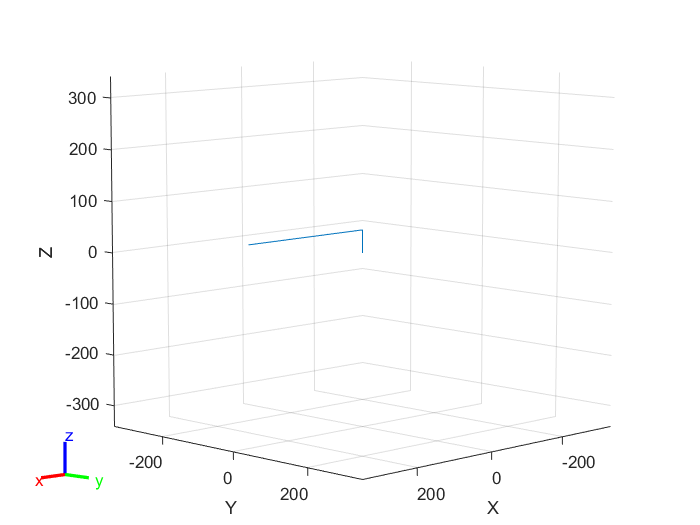

figure(Name="Robot Model")
show(robot);

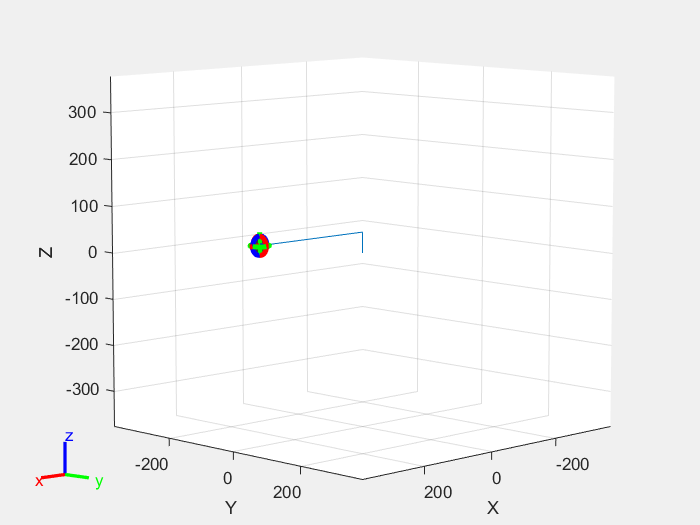

figure(Name="Interactive GUI")
gui = interactiveRigidBodyTree(robot, MarkerScaleFactor=100);